# FF_VFI_AZ_VEC Dynamic Savings Problem Vectorized Common Grid

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

This is the example vignette for function: [**ff_vfi_az_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_vec.m) from the [**MEconTools Package**](https://fanwangecon.github.io/MEconTools/)**. **This function solves (vectorized) the dynamic programming problem for a (a,z) model. Households can save a, and face AR(1) shock z. The problem is solved over the infinite horizon. 

The code uses common grid, with the same state space and choice space grids. [**ff_vfi_az_bisec_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_bisec_vec.m) from the [**MEconTools Package**](https://fanwangecon.github.io/MEconTools/) solves the same problem but using continuous exact percentage asset choices, which is more precise than the solution here, and perhaps a little bit slower. 

This is the vectorized code, its speed is much faster than the looped code. The function is designed to have small memory footprint and requires low computing resources, yet is fast.

**Links to Four Code:**

Four Core Savings/Borrowing Dynamic Programming Solution Functions that are functions in the [**MEconTools Package**](https://fanwangecon.github.io/MEconTools/)**. **:

- Common Choice and States Grid ***Loop***: [**ff_vfi_az_loop**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_loop.m), slow should use for testing new models

- Common Choice and States Grid ***Vectorized***:  [**ff_vfi_az_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_vec.m), fast good for many purposes

- States Grid + Continuous Exact Savings as Share of Cash-on-Hand ***Loop***:[** ff_vfi_az_bisec_loop**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_bisec_loop.m), high precision even with small grid

- States Grid + Continuous Exact Savings as Share of Cash-on-Hand ***Vectorized***: [**ff_vfi_az_bisec_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_bisec_vec.m), precision and speed

## Test FF_VFI_AZ_VEC Defaults

Call the function with defaults. By default, shows the asset policy function summary. Model parameters can be changed by the mp_params.

%mp_params
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('fl_crra') = 1.5;
mp_params('fl_beta') = 0.94;
ff_vfi_az_vec(mp_params);

Elapsed time is 0.128918 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
          i    idx    ndim    numel    rowN    colN     sum      mean      std     coefvari    min    max
          _    ___    ____    _____    ____    ____    _____    ______    _____    ________    ___    ___

    ap    1     1      2       700     100      7      16864    24.091    14.08    0.58446      0     50 

xxx TABLE:ap xxxxxxxxxxxxxxxxxx
              

## Test FF_VFI_AZ_BISEC_VEC Speed Tests

Call the function with different a and z grid size, print out speed:

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_timer') = true;
mp_support('ls_ffcmd') = {};

A grid 200, shock grid 9:

mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 200;
mp_params('it_z_n') = 9;
ff_vfi_az_vec(mp_params, mp_support);

Elapsed time is 0.220867 seconds.


A grid 750, shock grid 15:

mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 750;
mp_params('it_z_n') = 15;
ff_vfi_az_vec(mp_params, mp_support);

Elapsed time is 3.573648 seconds.


A grid 600, shock grid 45:

mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 600;
mp_params('it_z_n') = 45;
ff_vfi_az_vec(mp_params, mp_support);

Elapsed time is 8.398580 seconds.


## Test FF_VFI_AZ_VEC Control Outputs

Run the function first without any outputs;

mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 50;
mp_params('it_z_n') = 5;
mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_timer') = false;
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;

Run the function and show policy function for savings choice. For ls_ffcmd, ls_ffsna, ls_ffgrh, can include these: 'v', 'ap', 'c', 'y', 'coh', 'savefraccoh'. These are value, aprime savings choice, consumption, income, cash on hand, and savings fraction as cash-on-hand.

Elapsed time is 0.014484 seconds.
xxx  ff_vfi_az_vec, outcome=savefraccoh  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group      a       mean_z_0_54195    mean_z_0_66401    mean_z_0_88162    mean_z_1_3095    mean_z_2_2745
    _____    ______    ______________    ______________    ______________    _____________    _____________

      1           0             0                 0                 0                 0           0.3505   
      2      1.0204             0                 0           0.46928           0.37487          0.51572   
      3      2.0408       0.36632           0.34687           0.63373           0.54163          0.61186   
      4      3.0612       0.53265           0.51178           0.47837           0.63592          0.67476   
      5   

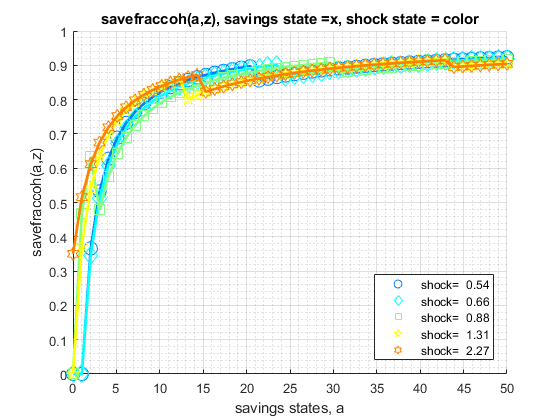

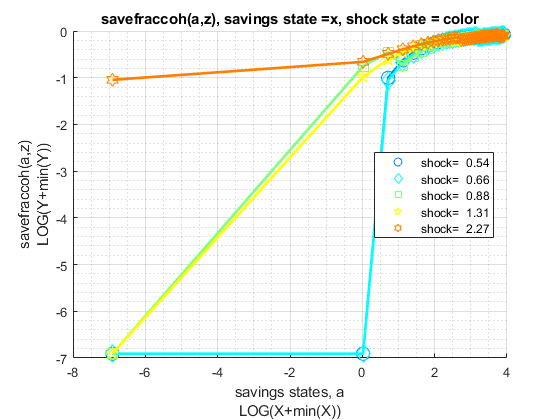

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
% ls_ffcmd: summary print which outcomes
mp_support('ls_ffcmd') = {};
% ls_ffsna: detail print which outcomes
mp_support('ls_ffsna') = {'savefraccoh'};
% ls_ffgrh: graphical print which outcomes
mp_support('ls_ffgrh') = {'savefraccoh'};
ff_vfi_az_vec(mp_params, mp_support);

Run the function and show summaries for savings and fraction of coh saved:

mp_params('it_a_n') = 100;
mp_params('it_z_n') = 9;
mp_support('ls_ffcmd') = {'ap', 'savefraccoh'};
mp_support('ls_ffsna') = {};
mp_support('ls_ffgrh') = {};
mp_support('bl_vfi_store_all') = true; % store c(a,z), y(a,z)
ff_vfi_az_vec(mp_params, mp_support);

Elapsed time is 0.127807 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    _______

    ap             1     1      2       900     100      9       21825      24.25     14.089      0.581      0          50
 

## Test FF_VFI_AZ_VEC Change Interest Rate and Discount

Show only save fraction of cash on hand:

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
mp_support('ls_ffcmd') = {'savefraccoh'};
mp_support('ls_ffsna') = {};
mp_support('ls_ffgrh') = {};
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 750;
mp_params('it_z_n') = 9;
mp_params('fl_a_max') = 50;
mp_params('st_grid_type') = 'grid_powerspace';

Solve the model with several different interest rates and discount factor:

% Lower Savings Incentives
mp_params('fl_beta') = 0.80;
mp_params('fl_r') = 0.01;
ff_vfi_az_vec(mp_params, mp_support);

Elapsed time is 0.771613 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    _______

    savefraccoh    1     1      2      6750     750      9      3318.8    0.49167    0.27768    0.56477      0     0.80542



% Higher Savings Incentives
mp_params('fl_beta') = 0.95;
mp_params('fl_r') = 0.04;
ff_vfi_az_vec(mp_params, mp_support);

Elapsed time is 2.484993 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    _______

    savefraccoh    1     1      2      6750     750      9      4491.9    0.66547    0.28771    0.43234      0     0.93029



## Test FF_VFI_AZ_VEC Changing Risk Aversion

Here, again, show fraction of coh saved in summary tabular form, but also show it graphically.

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
mp_support('ls_ffcmd') = {'savefraccoh'};
mp_support('ls_ffsna') = {};
mp_support('ls_ffgrh') = {'savefraccoh'};
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 750;
mp_params('it_z_n') = 9;
mp_params('fl_a_max') = 50;
mp_params('st_grid_type') = 'grid_powerspace';

Solve the model with different risk aversion levels, higher preferences for risk:

Elapsed time is 1.991475 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean       std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    ______    ________    ___    _______

    savefraccoh    1     1      2      6750     750      9      3735.9    0.55347    0.2897    0.52343      0     0.85998

xxx

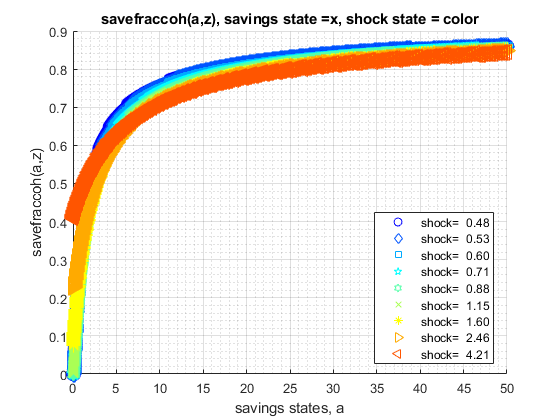

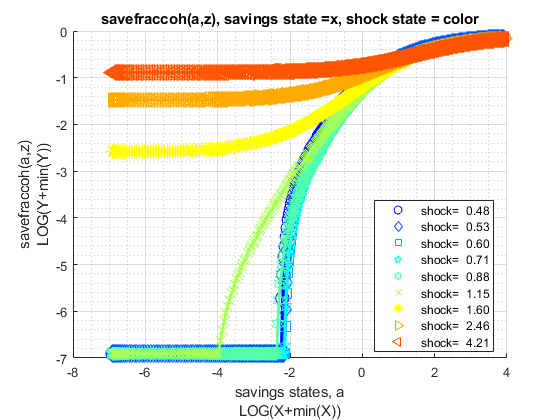

% Lower Risk Aversion
mp_params('fl_crra') = 0.5;
ff_vfi_az_vec(mp_params, mp_support);

When risk aversion increases, at every state-space point, the household wants to save more.

Elapsed time is 2.026442 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean       std      coefvari    min     max 
                   _    ___    ____    _____    ____    ____    ______    ______    _______    ________    ___    _____

    savefraccoh    1     1      2      6750     750      9      4639.3    0.6873    0.28204    0.41036      0     0.942

xxx TABLE

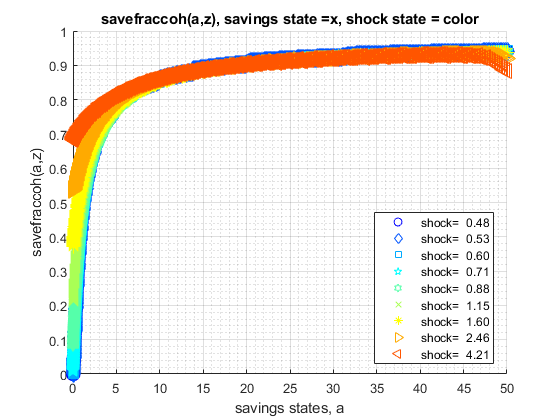

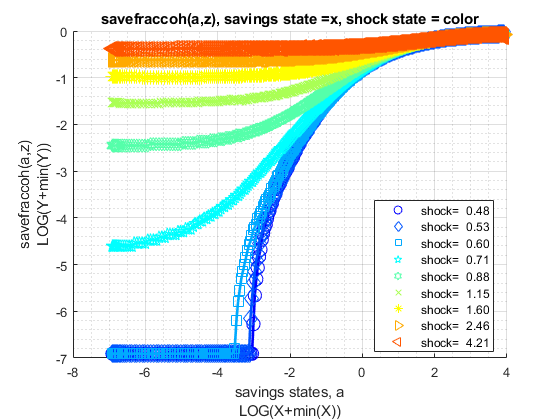

% Higher Risk Aversion
mp_params('fl_crra') = 5;
ff_vfi_az_vec(mp_params, mp_support);

## Test FF_VFI_AZ_VEC with Higher Uncertainty

Increase the standard deviation of the Shock. 

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
mp_support('ls_ffcmd') = {'savefraccoh'};
mp_support('ls_ffsna') = {};
mp_support('ls_ffgrh') = {};
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 750;
mp_params('it_z_n') = 9;
mp_params('fl_a_max') = 50;
mp_params('st_grid_type') = 'grid_powerspace';

Lower standard deviation of shock:

% Lower Risk Aversion
mp_params('fl_shk_std') = 0.10;
ff_vfi_az_vec(mp_params, mp_support);

Elapsed time is 2.065989 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN    sum      mean        std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ____    _______    _______    ________    ___    _______

    savefraccoh    1     1      2      6750     750      9      4026    0.59644    0.31533    0.52869      0     0.91423

xxx TA

Higher shock standard deviation: low shock high asset save more, high shock more asset save less, high shock low asset save more:

% Higher Risk Aversion
mp_params('fl_shk_std') = 0.40;
ff_vfi_az_vec(mp_params, mp_support);

Elapsed time is 2.184888 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min     max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    ______

    savefraccoh    1     1      2      6750     750      9      4687.4    0.69442    0.27109    0.39038      0     0.9339

xxx